% b = 1
% t = 1
% 
% CV_RED = cell(10,6);
% CV_GREEN = cell(10,6);
% CV_BLUE = cell(10,6);
% CV_WHITE = cell(10,6);
% for b = 1:10
%     for t = 1:6
%         CV_RED{b,t} = R_dev{b,t}./RED{b,t}*100; % coefficient of variation
%         CV_GREEN{b,t} = G_dev{b,t}./GREEN{b,t}*100;
%         CV_BLUE{b,t} = B_dev{b,t}./BLUE{b,t}*100;
%         CV_WHITE{b,t} = W_dev{b,t}./WHITE{b,t}*100;
%     end
% end
direc = "CVboxplots"

direc = "CVboxplots"

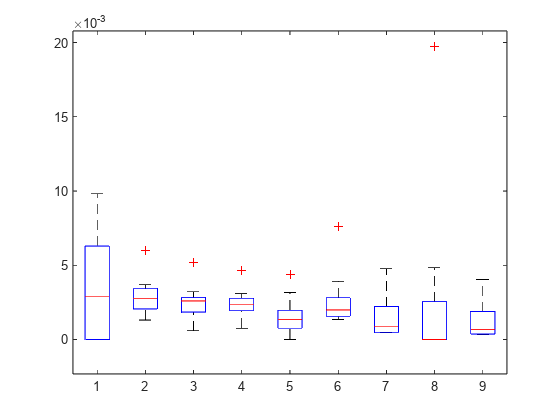

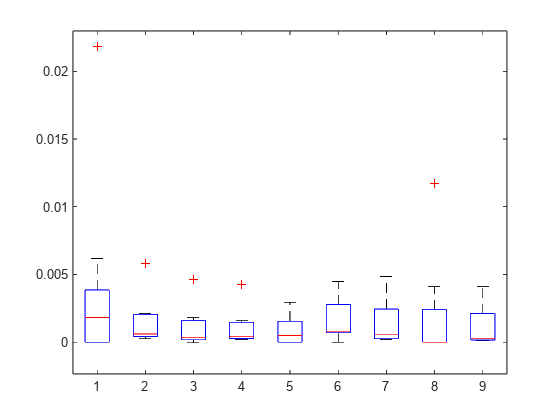

CV_plots(WHITE, W_dev, 'White', direc);

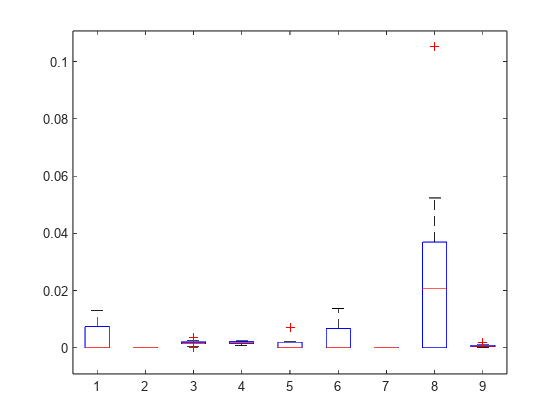

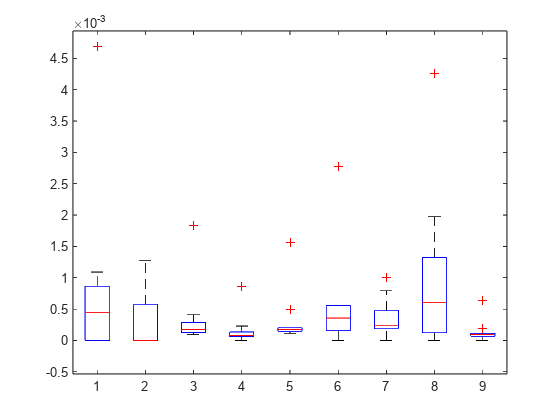

CV_plots(RED, R_dev, 'Red', direc);
CV_plots(GREEN,G_dev, 'Green', direc);

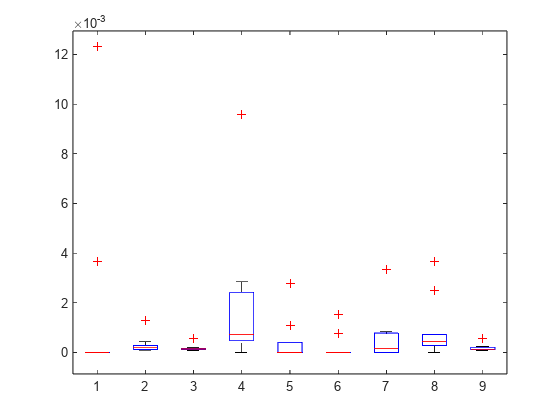

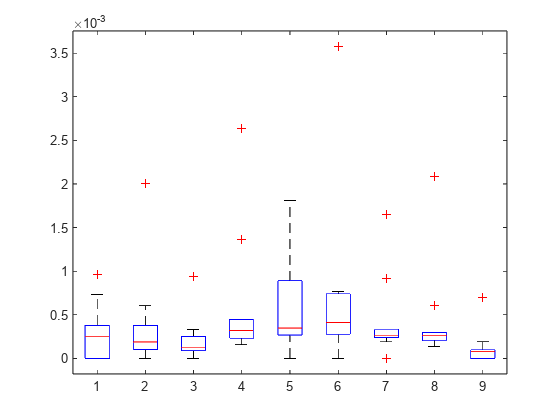

CV_plots(BLUE,B_dev, 'Blue', direc);



Rdev = cell2mat(R_dev(:,1))

Rdev =          0         0         0    0.5026         0         0         0    0.5104         0         0    0.4104         0         0         0         0
         0         0         0    0.4894         0         0    0.4894    0.5130    0.3940         0    0.3663    0.5104    0.3078         0         0
         0         0         0    0.4104         0    0.3078    0.5026    0.4443    0.5130    0.5104    0.4702    0.4702         0    0.5104         0
         0         0         0    0.4894         0    0.5525    0.5501    0.4702    0.5104    0.3663    0.4894    0.3663         0    0.3078         0
         0         0         0    0.4104    0.3663    0.6070    0.6048    0.5104    0.5026    0.4894    0.7452    0.3078         0    0.4702         0
         0         0         0         0         0    0.4104    0.4894    0.5026    0.3244         0    0.6708    0.3940         0    0.5026         0
    0.5026         0         0         0         0    0.6387    0.5982    0.3663    0.4

R = cell2mat(RED(:,1))

R = 1.0e+03 *

    0.0030    0.0020    0.0040    0.0056    0.0030    0.0940    0.2660    0.0035    0.1590    0.0170    0.1372    0.0450    0.0150    0.1360    0.0400
    0.0070    0.0030    0.0070    0.0117    0.0050    0.1930    0.5524    0.0075    0.3281    0.0360    0.2851    0.0925    0.0339    0.2810    0.0400
    0.0100    0.0050    0.0110    0.0178    0.0080    0.2919    0.8436    0.0118    0.4995    0.0545    0.4353    0.1397    0.0530    0.4275    0.0400
    0.0140    0.0060    0.0150    0.0234    0.0110    0.3879    1.1338    0.0157    0.6705    0.0742    0.5848    0.1868    0.0710    0.5719    0.0400
    0.0170    0.0080    0.0190    0.0302    0.0132    0.4905    1.4501    0.0206    0.8556    0.0956    0.7464    0.2369    0.0910    0.7277    0.0400
    0.0210    0.0100    0.0230    0.0370    0.0170    0.5902    1.7792    0.0256    1.0460    0.1200    0.9126    0.2871    0.1110    0.8864    0.0400
    0.0254    0.0120    0.0270    0.0450    0.0200    0.7027    2.1476    0.030

CV_R = Rdev./R

CV_R =          0         0         0    0.0898         0         0         0    0.1479         0         0    0.0030         0         0         0         0
         0         0         0    0.0420         0         0    0.0009    0.0684    0.0012         0    0.0013    0.0055    0.0091         0         0
         0         0         0    0.0231         0    0.0011    0.0006    0.0378    0.0010    0.0094    0.0011    0.0034         0    0.0012         0
         0         0         0    0.0210         0    0.0014    0.0005    0.0299    0.0008    0.0049    0.0008    0.0020         0    0.0005         0
         0         0         0    0.0136    0.0279    0.0012    0.0004    0.0248    0.0006    0.0051    0.0010    0.0013         0    0.0006         0
         0         0         0         0         0    0.0007    0.0003    0.0196    0.0003         0    0.0007    0.0014         0    0.0006         0
    0.0198         0         0         0         0    0.0009    0.0003    0.0122    0.0

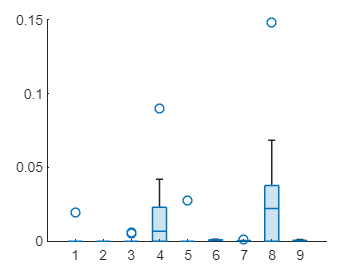

boxchart(CV_R(:,1:9))

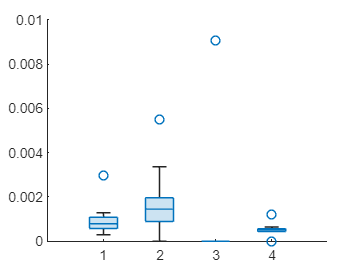


boxchart(CV_R(:,11:14))

function CV_plots(COLOUR, C_dev , colour, direc)
    AS_Colours = flip([0.7 0 1; 0 0 1; 0 1 1; 0 1 0; 1 1 0; 1 0.6 0; 1 0 0; 0.7 0 0; 0 0 0]);
    VEML_Colours = flip([1 0 0; 0 1 0; 0 0 1; 0 0 0]);
    t_int = dictionary(1:6,[40, 80, 160, 320, 640, 1280]);
    for t = 1:6
        Cdev = cell2mat(C_dev(:,t));
        C = cell2mat(COLOUR(:,t));
        CV_C = Cdev./C;
        CV_AS = CV_C(:,1:9);
        CV_VEML = CV_C(:,11:14);

        % ------------------------------------------------------------------
        f = figure();
        boxplot(CV_AS,'PlotStyle','traditional')


        % Get handles to the individual box objects
        h = findobj(gca,'Tag','Box');
        
        % Set the colors for each box using your AS_Colours
        for i = 1:length(h)
            patch(get(h(i),'XData'),get(h(i),'YData'),AS_Colours(i,:),'FaceAlpha',0.5);
        end

        grid on
        x_labels = {"CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR"};
        % xticks(0:10);
        xticklabels(x_labels);
        % ylim([0,1.05]);
        xlabel("Channel",'FontSize',14);
        ylabel("Coefficient of Variation (%)",'FontSize',14)
        ylim([0,0.1])
        plot_title = sprintf("AS7341 Coefficient of Variation for %s Input", colour);
        title(plot_title,'FontSize', 18)
        plot_subtitle = sprintf("t_{int} = %d ms", t_int(t));
        subtitle(plot_subtitle,'FontSize',12)
        set(gcf,'units','normalized','outerposition',[0 0 0.4 0.6]);
    
        filename = sprintf("%s/AS_ALL_CV_%s_%d.jpg",direc,colour,t_int(t));
        saveas(f,filename)
        close(f);

        % ------------------------------------------------------------------
        f = figure();
        boxplot(CV_VEML,'PlotStyle','traditional')

        % Get handles to the individual box objects
        h = findobj(gca,'Tag','Box');
        
        % Set the colors for each box using your AS_Colours
        for i = 1:length(h)
            patch(get(h(i),'XData'),get(h(i),'YData'),VEML_Colours(i,:),'FaceAlpha',0.5);
        end

        grid on
        x_labels = {"RED","GREEN","BLUE","CLEAR"};
        % xticks(0:10);
        xticklabels(x_labels);
        % ylim([0,1.05]);
        xlabel("Channel",'FontSize',14);
        ylabel("Coefficient of Variation (%)",'FontSize',14)
        ylim([0,0.05])
        plot_title = sprintf("VEML6040 Coefficient of Variation for %s Input", colour);
        title(plot_title,'FontSize', 18)
        plot_subtitle = sprintf("t_{int} = %d ms", t_int(t));
        subtitle(plot_subtitle,'FontSize',12)
        set(gcf,'units','normalized','outerposition',[0 0 0.4 0.6]);
    
        filename = sprintf("%s/VEML_CV_%s_%d.jpg",direc,colour,t_int(t));
        saveas(f,filename)
        close(f);
    end
end

% function CV_plots(CV_COLOUR, colour, direc)
%     t_int = dictionary(1:6,[40, 80, 160, 320, 640, 1280]);
%     for t = 1:6
%         C = cell2mat(CV_COLOUR(:,t))
%         C_AS = C(1:8,1:9);
%         C_VEML = C(:,11:14);
% 
%         f = figure();
%         boxplot(C_AS,'PlotStyle','traditional')
%         grid on
%         x_labels = {"CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR"};
%         % xticks(0:10);
%         xticklabels(x_labels);
%         % ylim([0,1.05]);
%         xlabel("Channel",'FontSize',14);
%         ylabel("Coefficient of Variation (%)",'FontSize',14)
%         plot_title = sprintf("AS7341 Coefficient of Variation for %s Input", colour);
%         title(plot_title,'FontSize', 18)
%         plot_subtitle = sprintf("t_{int} = %d ms", t_int(t));
%         subtitle(plot_subtitle,'FontSize',12)
%         set(gcf,'units','normalized','outerposition',[0 0 0.4 0.6]);
% 
%         filename = sprintf("%s/AS_ALL_CV_%s_%d.jpg",direc,colour,t_int(t));
%         saveas(f,filename)
%         close(f);
% 
%         % -------------------------------------------------------------------
%         f = figure();
%         boxplot(C_VEML,'PlotStyle','traditional')
%         grid on
%         x_labels = {"RED","GREEN","BLUE","CLEAR"};
%         % xticks(0:10);
%         xticklabels(x_labels);
%         % ylim([0,1.05]);
%         xlabel("Channel",'FontSize',14);
%         ylabel("Coefficient of Variation (%)",'FontSize',14)
%         ylim([0,1])
%         plot_title = sprintf("VEML6040 Coefficient of Variation for %s Input", colour);
%         title(plot_title,'FontSize', 18)
%         plot_subtitle = sprintf("t_{int} = %d ms", t_int(t));
%         subtitle(plot_subtitle,'FontSize',12)
%         set(gcf,'units','normalized','outerposition',[0 0 0.4 0.6]);
% 
%         filename = sprintf("%s/VEML_CV_%s_%d.jpg",direc,colour,t_int(t));
%         saveas(f,filename)
%         close(f);
%     end
% end